# Ekuazio diferentzialak

Tutorial honetan ikusiko dugu nola lan egin ekuazio diferentzialekin, eta nola irudikatu haien emaitzak

clear all %Zeuden adagai guztiak garbitzeko

## Ekuazio diferentzialen ebazpena kalkulu sinbolikoa erabiliz: lehen mailako ekuazioak

Matlabeko pakete sinbolikoak ahalbidetzen du ekuazio diferentzial errezen ebazpena emateko. Erabil dezagun $\dot x=2x$ ekuazioa ebazteko. 

syms x(t) % y funtzio sinbolikoa eta t aldagai sinbolikoak direla adierazi

Ekuazioa ebazteko dsolve erabili behar da. Berdin == bezala adierazten dela  eta deribatuak diff komandoarekin sartzen dira. Gogoratu zehatz-mehatz diff(funtzioa(aldagaia),n) sartu behar da, n. ordeneko deribatua kalkulatzeko. n. balioa autazkoa da, ezer jartzekotan n=1 bezala hartuko du.

dsolve(diff(x(t))== 2*x(t))

$$ans = C_{1}\,{\mathrm{e}}^{2\,t}$$

Konstante bat agertzen da; izan ere, dsolve-k sistemaren soluzio guztiak ematen dizkizu. Baina dsolvek ere ahalbidetzen digu hasierako balio bat finkatzea, bigarren ekuazio bat sartuz; izan ere, bai, ekuazioaren soluzioa funtzio sinboliko batean gorde dezakegu, eta erabili dezakegu notazio berbera bi aldeetan.

x(t)=dsolve(diff(x(t))== 2*x(t),x(0)==1)

$$x(t) = {\mathrm{e}}^{2\,t}$$

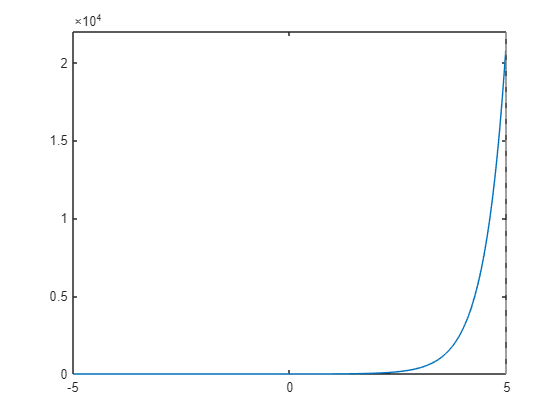

fplot(x)%fplot erabiliz erraz lor dezakegu funtzio horren irudia.

clear x t

## Ekuazio diferentzialen ebazpena bigarren mailako kalkulu sinbolikoa

Suposatu $\ddot  x+x=0$ren emaitzak kalkulatu nahi ditugula. Hasteko, ebazpen orokorra erraz lor dezakegu:

syms x(t) y(t)

Gogoratu, zenbaki batekin esan ahal zaio zenbat alditan deribatzen ari garen.  Aurrekoan atalean bezala hasierako balioak zehaz ditzakegu. Horretarako, $x$-ren deribatua aldagai sinboliko bat bezala adierazi behar dugu 

dsolve(diff(x(t),2)+x(t)==0)

$$ans = C_{1}\,\cos\left(t\right)-C_{2}\,\sin\left(t\right)$$

Jarraitzeko idatze dezagun hasierako balioak. Horretarako, $y=\dot x$ definituko dugu:

[x(t),y(t)]=dsolve(diff(x)==y(t), diff(y)+x==0,x(0)==1, y(0)==1)

$$x(t) = \cos\left(t\right)+\sin\left(t\right)$$

$$y(t) = \cos\left(t\right)-\sin\left(t\right)$$

Jarraitzeko, $x$ eta bere deribatuaren grafikoak egingo ditugu: 

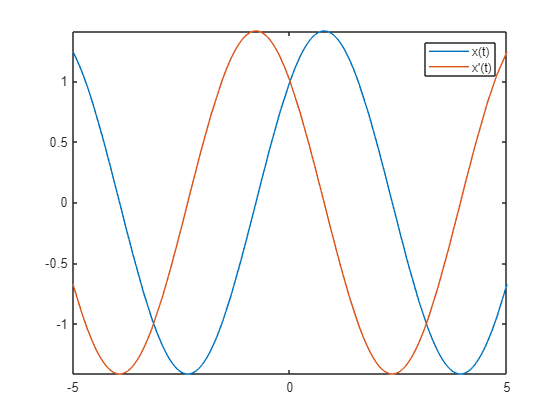

fplot([x,y])%fplot funtzio bat baino gehiago irudika ditzake aldi berean
legend("x(t)", "x'(t)")%Jakiteko zer den kurba bakoitza. 

Jarraitzeko, irudikatuko dugu y eta bere deribatua fase planoan: 

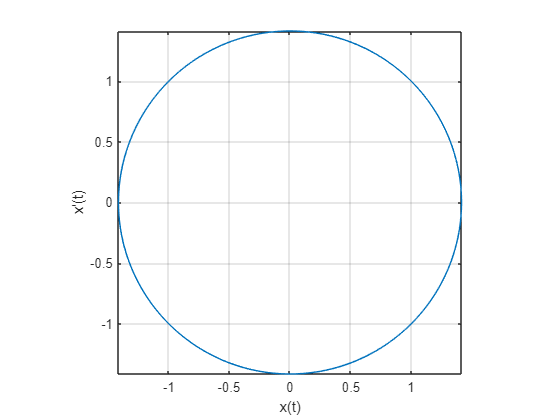

fplot(x,y) %Funtzioa eta deribatua osatzen duten fase diagrama adierazteko;
%izan ere, kortzeterik gabe (y(t),z(t)) kurba marraztuko du.  
axis equal %Ardatzak berdinak izateko. Oso garrantzitsua efekto optikorik ez izateko
grid on % Ardatzekiko paraleloak diren lerroak sortzeko.  
xlabel("x(t)")%Jakiteko zer esan nahi duen lehen koordenatua grafikoan. 
ylabel("x'(t)")%Jakiteko zer esan nahi duen bigarren koordenatua grafikoan. 

clear x y t %aldagaiak sinboliokak izaten uzteko.

## Ekuazio diferentzialen hurbilpenak

%Batzutan ezin da ekuazio diferentzial baten emaitza zehatza jakin, solik lor daiteke hurbilpen bat zenbakizko metodoak erabiliz. Adibidez $\dot x=\max(0,t-1)x$ ebazteko, oso ekuazio diferentzial sinplea dena, pakete sinbolikoak ezin dizu egin. Kendu portzentajea hurrengo bi lerroei eta kusi nola ematen duen akats bat:

%syms y(t)
%dsolve(diff(y(t),2)+max([0 t-1])*y(t)==0)

%Ekuazio hori ebaztkeo, funtzio anonimoak eta ode45 erabili behar dugu. Kontuan izan behar dugu ode45 $\dot x=f(t,x)$; $x(0)=x^0$ motako sistemak ebazten dituela. Emaitza, itzultzen dizuna, izango da zein balioetan huribildu dituen emaitzak eta zein den hurbilpen hori. Ebatz dezagun $\dot x=\max(0,t-1)x$ hasierako balioa $x(0)=1$ baldin bada, Matlabeko agindua ode45(@funtzioa, denbora tartea, hasierako balioa) da.  

f=@(t,x) max([0, t-1]);
[t,x]=ode45(f,[0 3],1)

t =          0
    0.0750
    0.1500
    0.2250
    0.3000
    0.3750
    0.4500
    0.5250
    0.6000
    0.6750


x =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


%ode45 ematen diguna puntuak dira, ez funtzioak. Hortaz, plot batekin erraz irudika ditzakegu.

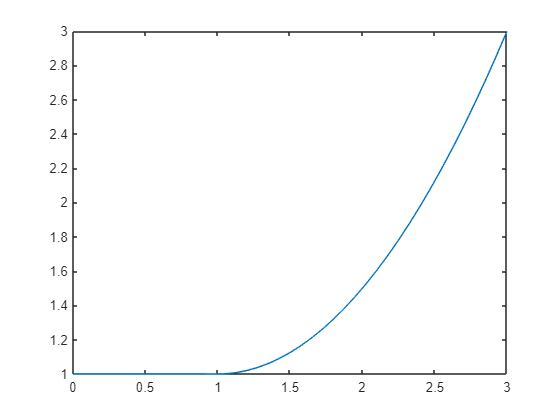

plot(t,x)%puntuak irudikatzen ditu, eta horiekin kurba bat interpolatzen du.

## Bigarren ordeneko ekuazioen hurbilpena.

Ebatz dezagun orain $\ddot x=-\max(t,t^2)x$, zein $x(0)=1$, $\dot x(0)=2$. Horretarako ode45 erabiliko dugu, kontuan izanik era matrizialean izatzi behar dugu. Horreterako, $z$ bektore bat definitu behar dugu zein $z_1=x$ eta $z_2= \dot x$.

f=@(t,z) [z(2) ;-max([t,t.^2])*z(1)]; %Kontuan izan z=[x;x'] izango dela
[t,x]=ode45(f,[0 10],[1;2]);

Ez ahaztu modu bektorial batean $ z(2)=\dot y$ denez, $\dot z(1)=z(2) $ dugula. ode45 sistema matrizialak ebatziko ditu. Jarriztko, marraz daiteke bi kurba bezala edo diagrama fase bezala. Kontuan izan $z$ matrize bat dela, lehenengo zutabea dela $y$, eta bigarrena $\dot y$. Irudika ditzagun $y$ eta $\dot y$.

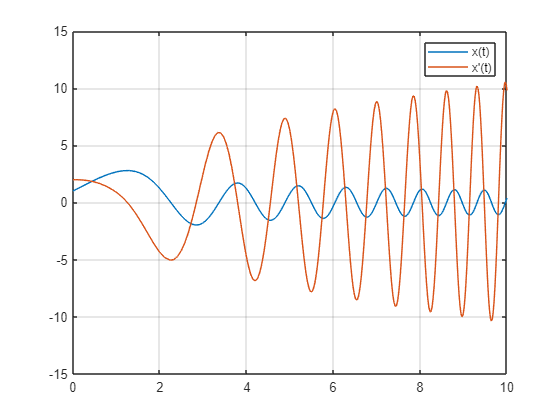

plot(t,x(:,1),t,x(:,2))
legend("x(t)", "x'(t)")
grid on

Gogoratu hau ere fase diagrama batean adieraz dezakegula:

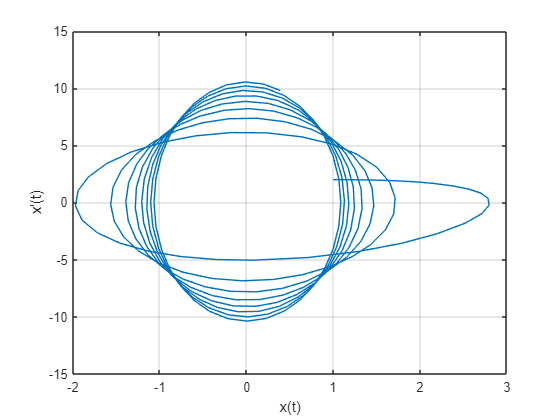

plot(x(:,1),x(:,2))
grid on
xlabel("x(t)")%Jakiteko zer esan nahi duen lehen koordenatua grafikoan. 
ylabel("x'(t)")%Jakiteko zer esan nahi duen bigarren koordenatua grafikoan. 

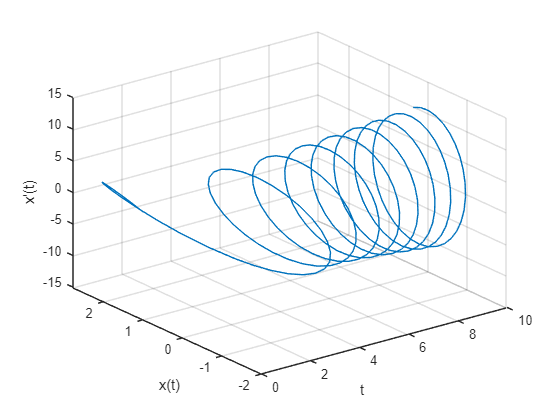

%Azkenik, ere irudika dezakegu hiru dimentsiotako grafiok batean:
plot3(t,x(:,1),x(:,2))
xlabel("t")
ylabel("x(t)")
zlabel("x'(t)")
grid on

clear t z

## Sistema autonomoak eta Matlab.

Hasteko, sistema autonomoak linealak direnean kalkulu sinbolikoa erabiliz erraz ebatz ditzakegu. Suposatu $\dot x=x+y$ eta $\dot y=x-y$ ebatzi nahi dugula. 

syms x(t) y(t)
dsolve(diff(x(t))==x(t)+y(t),diff(y(t))==x(t)-y(t))

ans = struct with fields:
    y: C1*exp(2^(1/2)*t) + C2*exp(-2^(1/2)*t)
    x: C1*exp(2^(1/2)*t)*(2^(1/2) + 1) - C2*exp(-2^(1/2)*t)*(2^(1/2) - 1)


Ikusten denez, dsolvek sistemak ere egiten dizu. Kasu honetan estruktura bat itzultzen du, Matlabeko bi aldagieko egiturarekin. Aurrekoan bezala, hasierako balioak ere finka daitezke

[x(t), y(t)]= dsolve(diff(x(t))==x(t)+y(t),diff(y(t))==x(t)-y(t), x(0)==1, y(0)==0);

Kurba fase diagrama batean marraz dezagu: 

fplot(x,y,[-2 2])%Denbora tartean finkatzen dugu ondo ikusteko. 
xlabel("x(t)")
ylabel("y(t)")

Beste aukera bat da norabide bektorea puntu bakoitzean irudikatzea. Horretarako quiver funtzioa erabili behar dugu

hold on
[x1 x2] =meshgrid(-15:.5:15) %Horrek planua puntuetan banatzen du x eta y 

x1 =   -15.0000  -14.5000  -14.0000  -13.5000  -13.0000  -12.5000  -12.0000  -11.5000  -11.0000  -10.5000  -10.0000   -9.5000   -9.0000   -8.5000   -8.0000   -7.5000   -7.0000   -6.5000   -6.0000   -5.5000   -5.0000   -4.5000   -4.0000   -3.5000   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000
  -15.0000  -14.5000  -14.0000  -13.5000  -13.0000  -12.5000  -12.0000  -11.5000  -11.0000  -10.5000  -10.0000   -9.5000   -9.0000   -8.5000   -8.0000   -7.5000   -7.0000   -6.5000   -6.0000   -5.5000   -5.0000   -4.5000   -4.0000   -3.5000   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    

x2 =   -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000  -15.0000
  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -14.5000  -1

% hor dauden balioak harturik.
x1fle= x1+x2%puntu bakoitzaren konponentea

x1fle =   -30.0000  -29.5000  -29.0000  -28.5000  -28.0000  -27.5000  -27.0000  -26.5000  -26.0000  -25.5000  -25.0000  -24.5000  -24.0000  -23.5000  -23.0000  -22.5000  -22.0000  -21.5000  -21.0000  -20.5000  -20.0000  -19.5000  -19.0000  -18.5000  -18.0000  -17.5000  -17.0000  -16.5000  -16.0000  -15.5000  -15.0000  -14.5000  -14.0000  -13.5000  -13.0000  -12.5000  -12.0000  -11.5000  -11.0000  -10.5000  -10.0000   -9.5000   -9.0000   -8.5000   -8.0000   -7.5000   -7.0000   -6.5000   -6.0000   -5.5000
  -29.5000  -29.0000  -28.5000  -28.0000  -27.5000  -27.0000  -26.5000  -26.0000  -25.5000  -25.0000  -24.5000  -24.0000  -23.5000  -23.0000  -22.5000  -22.0000  -21.5000  -21.0000  -20.5000  -20.0000  -19.5000  -19.0000  -18.5000  -18.0000  -17.5000  -17.0000  -16.5000  -16.0000  -15.5000  -15.0000  -14.5000  -14.0000  -13.5000  -13.0000  -12.5000  -12.0000  -11.5000  -11.0000  -10.5000  -10.0000   -9.5000   -9.0000   -8.5000   -8.0000   -7.5000   -7.0000   -6.5000   -6.0000   -5.5000 

x2fle= x1-x2%puntu bakoitzaren konponentea

x2fle =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000
   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000 

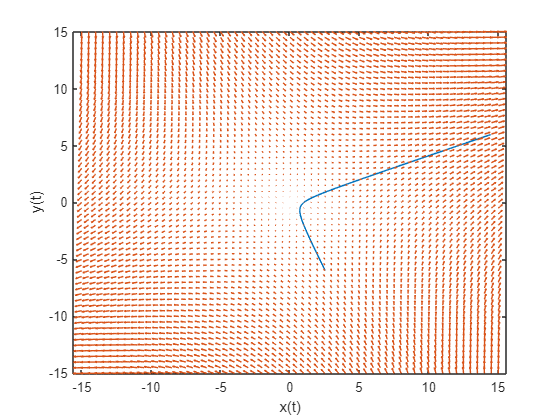

quiver(x1,x2,x1fle,x2fle)
hold off

clear x y t

## Sistema autonomo ez-linealak.

Azkenean, ikus dezagun zer egin sistema ez lineal bat dugunea, adibidez:


$$\begin{cases} \dot x=x^2+2y,\\ \dot y=5x+ y^2\end{cases}$$
 

Hasteko, erraz ikus daiteke jatorria puntu kritiko bakarra dela eta diferentziala 0-n  $\left\lbrack \begin{array}{cc}
0 & 2\\
5 & 0
\end{array}\right\rbrack$ matrizea dela. Horretarako, eigen funtzioarekin erraz kalkula daitezke bektore propioak:

eig([0 2; 5 0])

ans =     3.1623
   -3.1623


Balio propio positibo bat eta beste bat negatiboa egoteak esan nahi du zeladura puntua dela. qvid equinda eta ode45 erabilita erraz ikus daiteke hala dela:

[x1, x2] =meshgrid(-1:.05:2); 
x1fle= x1.^2+2*x2;%gogoratu.^eta .* idaztea eragiketak koordenatuka egiteko. 
x2fle= 5*x1+x2.^2;%gogoratu.^eta .* idaztea eragiketak koordenatuka egiteko.
quiver(x1,x2,x1fle,x2fle)

Adibidez, [0.25 0.35] puntuan hasiz gero kalkula daiteke ode45 erabiliz zer gertatzen den

f=@(t,z) [z(1)^2+2*z(2);5*z(1)+z(2)^2];
[t,z]= ode45(f,[0 1],[0.4;-0.6]);
hold on 
plot(z(:,1),z(:,2))

Baita ere egin daitezke kurba gehiago

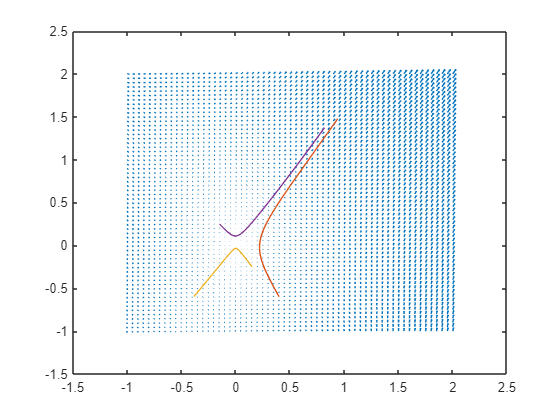

[t,z]= ode45(f,[0 2],[0.15;-0.25]);
plot(z(:,1),z(:,2))
[t,z]= ode45(f,[0 1.4],[-0.15;0.25]);
plot(z(:,1),z(:,2))
hold off